# Visualisation

This is the first approach on a good visualisation of a function $f: \mathbb{R}^2 \rightarrow \mathbb{R}$

%Using meshgrid
X = linspace(-5,5,1e2+1);
[X,Y] = meshgrid(X);


Now it's time to use our grid to evaluate some function on it.


$$f_1(x,y) = sin(x)\cdot cos(y)$$
 


$$f_2(x,y)=\frac{\sin(\sqrt{x+y})}{\sqrt{x+y}}$$



$$f_3(x,y) =\biggl |\left(1+\frac{1}{x} \biggr)^x-\left(1+\frac{1}{y} \biggr)^y \biggr | $$



$$f_4(x,y) = \sum_{k=1}^{17}\frac{\sin(x)^y }{k}$$



$$f_5(x,y) = \sin(x)y$$


## Function 1

This function will be plotted via a surface Graph combined with some contour

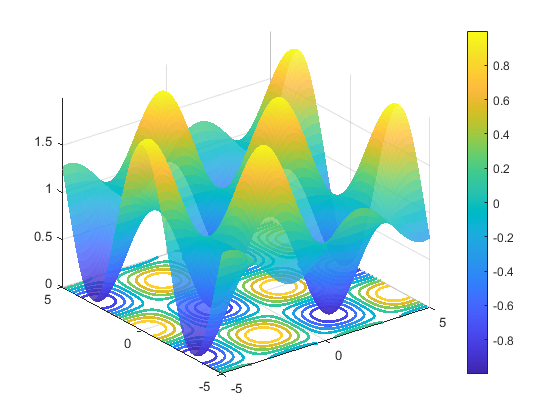

%Z = sin(X).*cos(Y);
Z = f1(X,Y);
C = Z;
s = surf(X,Y,Z+1,C,"FaceAlpha",0.8);

hold on
s.EdgeColor = 'none';
colorbar;
contour(X,Y,Z,8,"LineWidth",2)
hold off

## Function 2

This is a furthermore example and has the droplike appearance 


$$f_2(x,y)=\frac{\sin(\sqrt{x+y})}{\sqrt{x+y}}$$


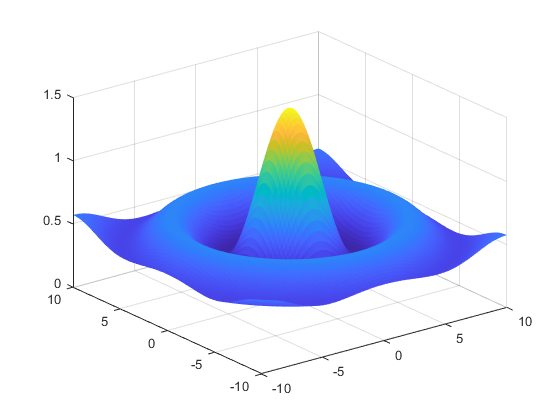

X = linspace(-10,10,1e2+1);
[X,Y] = meshgrid(X);

Z = f2(X,Y);
droplet = surf(X,Y,Z+0.5,"EdgeColor", 'none');

## Function 3

This plots the difference of the approaching exp function


$$f_3(x,y) =\biggl |\left(1+\frac{1}{x} \biggr)^x-\left(1+\frac{1}{y} \biggr)^y \biggr | $$


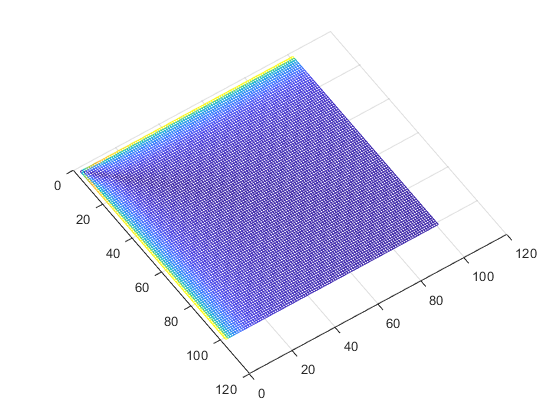

X = linspace(-1,10,1e2+1);
[X,Y] = meshgrid(X);

Z = f3(X,Y);

m = mesh(Z);

% A = axes
% set(A,'xScale','log')

## Function 4

I just wanted to also add some sums to make a discontinuos function and also I'm kind of curious


$$f_4(x,y) = \sum_{k=1}^{17}\frac{|\sin(x)|^y }{k}$$


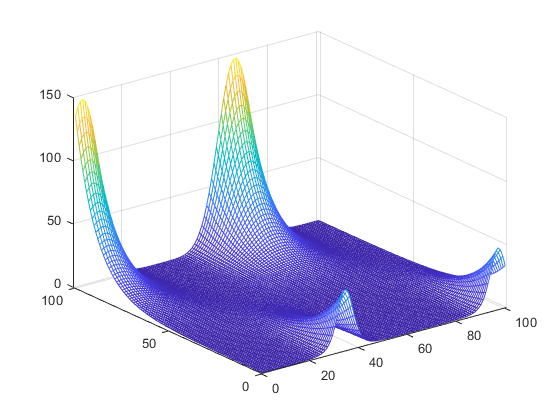

X = linspace(-5,5,1e2+1);
[X,Y] = meshgrid(X);
Z = f4(X,Y);
mesh(Z);

## Function 5

Combines the mesh with pcolor


$$f_5(x,y) = \sin(x)y+4$$


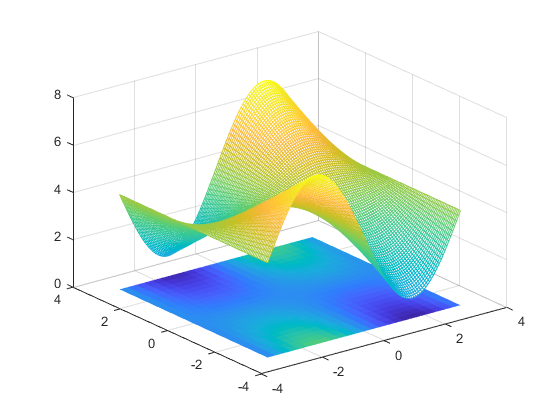

X = linspace(-pi,pi,1e2+1);
[X,Y] = meshgrid(X);
Z = f5(X,Y);
mesh(X,Y,Z+4);
hold on 
X = linspace(-pi,pi,25);
[X,Y] = meshgrid(X);
Z = f5(X,Y);
p = pcolor(X,Y,Z);
p.LineWidth = 0.125;
p.LineStyle = 'none';
hold off

## Higher Dimensional Plotting via animation

I think I'm choosing an easy function for this $g: \mathbb{R}^3 \rightarrow \mathbb{R}$


$$g(x,y,z)= 5z\cdot
(x+y)$$


I'm going to change the Z Coordinat with elapsing time and fix everything else

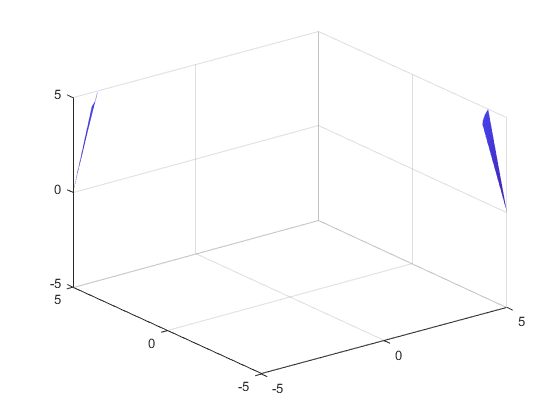

X =linspace(-5,5,101);
[X,Y] = meshgrid(X);
s = surf(X,Y,0.*X);
s.EdgeColor = 'none';
axis([-5,5,-5,5,-5,5]);
axis manual
 for Z = -5:0.1:5 %I am aware both notation give me the same array
     P = 5.*Z+(X.*Y);
     s.ZData = P;
     pause(0.1)
 end

Now we create a subplot with all Methods learned before

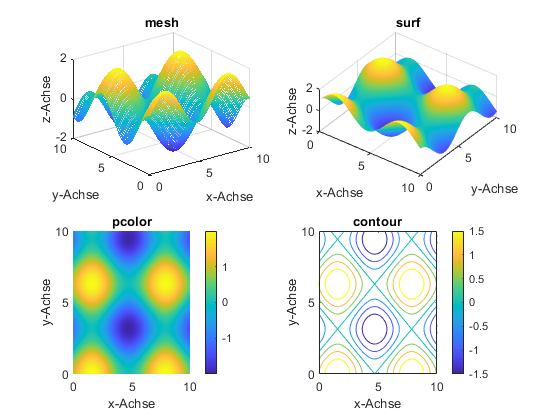

[x,y] = meshgrid(0:0.1:10, 0:0.1:10);

z = sin(x) + cos(y);

subplot(2,2,1);
mesh(x,y,z);
title("mesh");
xlabel("x-Achse");
ylabel("y-Achse");
zlabel("z-Achse");
alpha(0.5);

subplot(2,2,2);
s = surf(x,y,z);
s.EdgeColor = 'none';
title("surf");
xlabel("x-Achse");
ylabel("y-Achse");
zlabel("z-Achse");
view(37,59);
shading interp;

subplot(2,2,3);
pC = pcolor(x,y,z);
pC.LineStyle = 'none';
title("pcolor");
xlabel("x-Achse");
ylabel("y-Achse");
colorbar;

subplot(2,2,4);
contour(x,y,z);
title("contour");
xlabel("x-Achse");
ylabel("y-Achse");
colorbar;